% data = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv', 'ReadVariableNames',1);
% dates = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv');
% Confounding = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Confounding/Confounding_Dataset.csv', 'ReadVariableNames',1);

data = readtable('Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv', 'ReadVariableNames',1);
dates = readtable('Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv');
Confounding = readtable('Datasets/Confounding/Confounding_Dataset.csv', 'ReadVariableNames',1);
AQI_data = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/AQI_Features.csv')

AQI_data = 832×8 table
         State                  County                          CS                   MaxAQI    x90thPercentileAQI    MedianAQI    AQI_Class_KM    Extreme_AQI
    ________________    ______________________    _______________________________    ______    __________________    _________    ____________    ___________

    'Alabama'           'Baldwin'                 'BaldwinAlabama'                    129      52.667                 36.833      1               0          
    'Alabama'           'Colbert'                 'ColbertAlabama'                    115      49.667                 36.667      1               0          
    'Alabama'           'DeKalb'                  'DeKalbAlabama'       

AQI_Classes = AQI_data.AQI_Class_KM; 

NC = zeros(832,3);
NC(AQI_Classes==1,2) = 1;
NC(AQI_Classes==2,1) = 1;
NC(AQI_Classes==2,2) = 1;
NC(AQI_Classes==3,1) = 1;

Total_Population = (Confounding.TOT_POP);
cases = table2array(data(:,12:173));
cases = cases./Total_Population;

US = 256;
[rC, cC] = size(cases);
splines = zeros(rC,US);

for t = 1:rC
    casesS = cases(t,:);
    casesS = nonzeros(casesS); % non-zero cases 
    if length(casesS)>1
        x = [1:length(casesS)]';  % number of days since first case 
        f = fit(x, casesS, 'cubicinterp');
        xeval = linspace(1, length(casesS), US);
        sp_eval = f(xeval)';
        splines(t,:)= sp_eval;
    end 
end 

exemplar = mean(splines);
diff_splines = zeros(rC,US);

for t = 1:rC
    diff_splines(t,:) = splines(t,:)-exemplar;
end

% Linear Correlation btwn cases
xcor_total = corrcoef(diff_splines');
NodeNames = string([1:rC]);
NodeNames = cellstr(NodeNames);

new_diag = zeros(1,rC);
xcor_total(find(eye(size(xcor_total))))=new_diag; %removing self edges

G = graph(xcor_total);
%plot(G)

G_WEIGHTS = G.Edges.Weight;
edges = [-1:0.05:1];
h = histogram(G_WEIGHTS, edges);
title('Correlation Values')

% Edgeless Nodes vs Correlation Threshold Calculations 

threshL = [0.8:0.01:1];
num_zero_connections = zeros(size(threshL));

for t=1:length(threshL)
    xcor_thresh = xcor_total;
    xcor_thresh(xcor_thresh<threshL(t))=0;
    G = graph(xcor_thresh);
    D = degree(G);
    zero_con_idx = find(D==0);
    num_zero_connections(t) = length(zero_con_idx);
end 

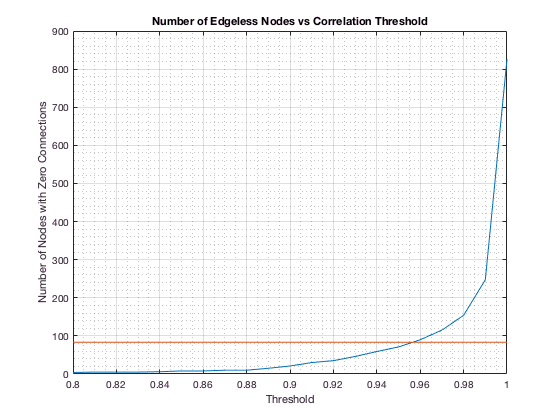

% Edgeless Nodes vs Correlation Threshold Plot 

five_pct = (832*0.10)*ones(size(threshL));
plot(threshL, num_zero_connections)
hold on; 
plot(threshL, five_pct)
xlabel('Threshold')
ylabel('Number of Nodes with Zero Connections')
title('Number of Edgeless Nodes vs Correlation Threshold')
hold off; 
grid on; 
grid minor; 

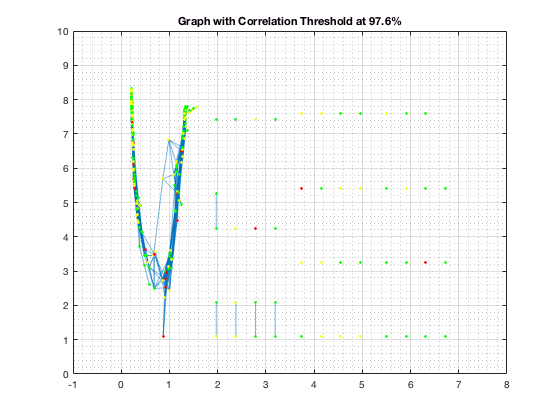

xcor_thresh = xcor_total;
thresh = 0.925; % 5 pct edgeless 
%thresh = 0.9564; % 10 pct edgeless
%thresh = 0.98
xcor_thresh(xcor_thresh<thresh)=0;

xcor_thresh = 1-xcor_thresh; 
xcor_thresh(xcor_thresh==1)=0;

G = graph(xcor_thresh, NodeNames);
%plot(G, 'NodeColor', NC, 'NodeLabel', NodeNames);
plot(G, 'NodeColor', NC);
title('Graph with Correlation Threshold at 97.6%')
grid on;
grid minor; 

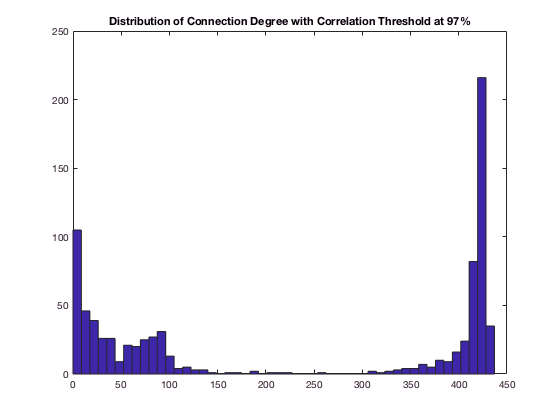


D = degree(G);
hist(D, 50);
title('Distribution of Connection Degree with Correlation Threshold at 97%')

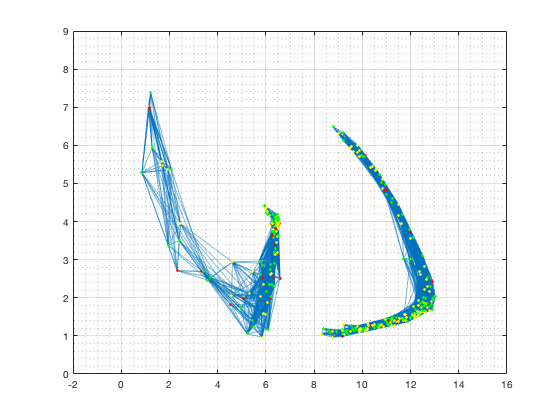


cut_degree = 10; 
min_cuts_idx = find(D<=cut_degree);
NC_cut = NC(D>cut_degree,:);
G_cut = rmnode(G, min_cuts_idx);
plot(G_cut, 'NodeColor',NC_cut)
grid on;
grid minor; 

% x = [1:US];
% plot(x, splines(16,:))
% plot(x, splines(658,:))
% plot(x, splines(518,:))
% plot(x, splines(519,:))
% plot(x, splines(582,:))
% plot(x, splines(18,:))
% plot(x, splines(687,:))
% plot(x, splines(684,:))
% plot(x, splines(144,:))

% xcor_mod = xcor_total;
% xcor_mod(xcor_mod>thresh)=0;
% 
% G_MOD = graph(xcor_mod, NodeNames);
%p = plot(G_MOD);

bins = conncomp(G)

bins =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1



LSUB = subgraph(G, find(bins == 1));
LSUB_idx = str2double(table2array(LSUB.Nodes))

LSUB_idx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


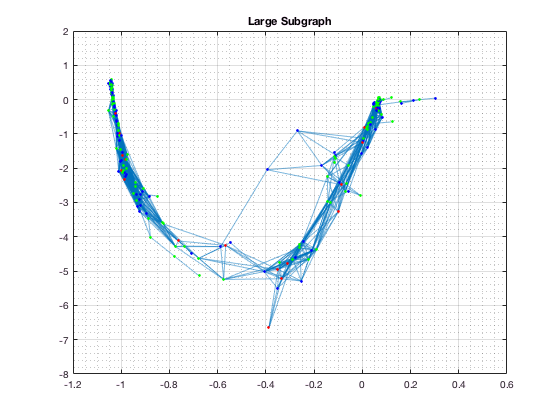

NC_LSUB = NC(LSUB_idx,:);
plot(LSUB, 'NodeColor', NC_LSUB)
grid on; 
grid minor; 
%plot(LSUB, 'NodeColor', NC_LSUB, 'LineStyle', ':')
title('Large Subgraph')


LSUB_Degree = degree(LSUB)

LSUB_Degree =    427
     9
     4
    20
   136
    12
   424
    73
    41
    14


sort(LSUB_Degree)

ans =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


min_cuts_idx = find(LSUB_Degree<10)

min_cuts_idx =      2
     3
    62
    93
   122
   131
   150
   154
   157
   162


NC_LSUB_Cuts = NC_LSUB

test = rmnode(LSUB, min_cuts_idx)

test =   graph with properties:

    Edges: [95794×2 table]
    Nodes: [719×1 table]


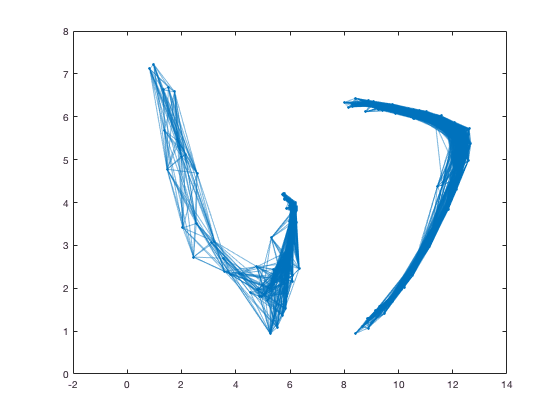

plot(test)


nn = numnodes(LSUB);
[s,t] = findedge(LSUB);
LSUB_adj = full(sparse(s,t,LSUB.Edges.Weight,nn,nn))

sub_thresh = LSUB_adj
thresh2 = 0.05
sub_thresh(sub_thresh>thresh2)=0;

LT = graph(sub_thresh)
plot(LT)


% D = degree(LSUB);
% histogram(D)
% title('Connection Degrees for Nodes in Large Subgraph')

%plot(Group1)
%plot(Outliers)
%plot(LSUB)

## Time to cluster the large subgroup - spectral clustering

% SC_Whole = spectralcluster(splines,3);
% classifications(:,1)=SC_Whole;
% 
% LSUB_Sim = adjacency(LSUB, 'weighted');
% LSUB_Sim_Full = full(LSUB_Sim);

% % LSUB into 3 Groups 
% SC3_LSUB = spectralcluster(LSUB_Sim_Full,3);
% 
% SC3_C1 = subgraph(LSUB, find(SC3_LSUB==1));
% SC3_C1_idx = str2double(table2array(SC3_C1.Nodes));
% classifications(SC3_C1_idx,2)=3;
% 
% SC3_C2 = subgraph(LSUB, find(SC3_LSUB==2));
% SC3_C2_idx = str2double(table2array(SC3_C2.Nodes));
% classifications(SC3_C2_idx,2)=4;
% 
% SC3_C3 = subgraph(LSUB, find(SC3_LSUB==3));
% SC3_C3_idx = str2double(table2array(SC3_C3.Nodes));
% classifications(SC3_C3_idx,2)=5;
% 

% % LSUB into 4 Groups 
% SC4_LSUB = spectralcluster(LSUB_Sim_Full,4);
% 
% SC4_C1 = subgraph(LSUB, find(SC4_LSUB==1));
% SC4_C1_idx = str2double(table2array(SC4_C1.Nodes));
% classifications(SC4_C1_idx,3)=3;
% 
% SC4_C2 = subgraph(LSUB, find(SC4_LSUB==2));
% SC4_C2_idx = str2double(table2array(SC4_C2.Nodes));
% classifications(SC4_C2_idx,3)=4;
% 
% SC4_C3 = subgraph(LSUB, find(SC4_LSUB==3));
% SC4_C3_idx = str2double(table2array(SC4_C3.Nodes));
% classifications(SC4_C3_idx,3)=5;
% 
% SC4_C4 = subgraph(LSUB, find(SC4_LSUB==4));
% SC4_C4_idx = str2double(table2array(SC4_C4.Nodes));
% classifications(SC4_C4_idx,3)=6;

% % LSUB into 5 Groups 
% SC5_LSUB = spectralcluster(LSUB_Sim_Full,5);
% SC5_C1 = subgraph(LSUB, find(SC5_LSUB==1));
% SC5_C1_idx = str2double(table2array(SC5_C1.Nodes));
% classifications(SC5_C1_idx,4)=3;
% 
% SC5_C2 = subgraph(LSUB, find(SC5_LSUB==2));
% SC5_C2_idx = str2double(table2array(SC5_C2.Nodes));
% classifications(SC5_C2_idx,4)=4;
% 
% SC5_C3 = subgraph(LSUB, find(SC5_LSUB==3));
% SC5_C3_idx = str2double(table2array(SC5_C3.Nodes));
% classifications(SC5_C3_idx,4)=5;
% 
% SC5_C4 = subgraph(LSUB, find(SC5_LSUB==4));
% SC5_C4_idx = str2double(table2array(SC5_C4.Nodes));
% classifications(SC5_C4_idx,4)=6;
% 
% SC5_C5 = subgraph(LSUB, find(SC5_LSUB==5));
% SC5_C5_idx = str2double(table2array(SC5_C5.Nodes));
% classifications(SC5_C5_idx,4)=7;

% T = data;
% T.SpectralClusteringWhole = classifications(:,1);
% T.SpectralClusteringK3 = classifications(:,2);
% T.SpectralClusteringK4 = classifications(:,3);
% T.SpectralClusteringK5 = classifications(:,4);

%T = table(SpectralClusteringWhole,SpectralClusteringK3,SpectralClusteringK4,SpectralClusteringK5)
%writetable(T,'Datasets/Spectral_Clustering_Classes.csv')